format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

# Opgave 1

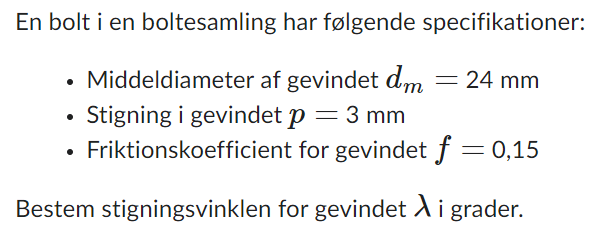

d_m = 24 * u.mm;
p = 3 * u.mm;
f = 0.15;
n = 1;
l = p * n;

lambda = atan(l/(pi*d_m)); %stigningsvinklen i gevind
vpa(lambda)

$$ans = 0.039767758602564109000518627114478$$

D = vpa(rad2deg( lambda ), 3) 

$$D = 2.28$$

# Opgave 2

clear
format shortG
u = symunit;

% f > separateUnits(tan(lambda))

# Opgave 3

clear
format shortG
u = symunit;

T_R = 19 * u.N * u.m

$$T\_R = 19\,N\,m$$

F = 22 * u.kN

$$F = 22\,\mathrm{kN}$$

p = 2 * u.mm

$$p = 2\,\mathrm{mm}$$

l = p

$$l = 2\,\mathrm{mm}$$


T_O = F*l/(2*pi) %Power ud uden friktion %ligning g

$$T\_O = \frac{22}{\pi }\,\mathrm{kN}\,\mathrm{mm}$$


% Virkningsgrad løft
e = T_O / T_R % = F*l/(2*pi*T_R) % ligning 8-4

$$e = \frac{22}{19\,\pi }\,\frac{\mathrm{kN}\,\mathrm{mm}}{N\,m}$$

e_ = vpa(unitConvert(e, "SI"), 3) % 0.37

$$e\_ = 0.369$$

# Opgave 4

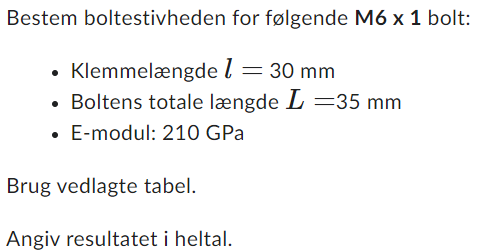

clear
format shortG
u = symunit;

d = 6 * u.mm;
A_t = 20.1 * u.mm^2;
A_r = 17.9 * u.mm^2;
p = 1 * u.mm;
l = 30 * u.mm;
L = 35 * u.mm;
E = 210 * u.GPa;
A_d = pi/4 * d^2;   % Skaftareal [mm^2]

if separateUnits(L) <= 125 && separateUnits(d) <= 48
    L_T = 2*d + 6 * u.mm
elseif 125 < separateUnits(L) && separateUnits(L) <= 200
    L_T = 2 * d + 12 * u.mm
elseif separateUnits(L) > 200
    L_T = 2 * d + 25 * u.mm
else
    disp("Hmmm something is wrong")
end

$$L\_T = 18\,\mathrm{mm}$$


l_d = L - L_T         % Skaft længde  [mm]

$$l\_d = 17\,\mathrm{mm}$$

l_t = l - l_d         % Gevindlængde i indgreb  [mm]

$$l\_t = 13\,\mathrm{mm}$$


%Stivhed for bolten når stykket uden og med gevind lægges sammen sammen
k_b = (A_d * A_t * E) / (A_d * l_t + A_t * l_d)

$$k\_b = \frac{37989\,\pi }{\frac{3417}{10}\,{\mathrm{mm}}^{3}+117\,\pi \,{\mathrm{mm}}^{3}}\,\mathrm{GPa}\,{\mathrm{mm}}^{4}$$

k_b = vpa(unitConvert((A_d * A_t * E) / (A_d * l_t + A_t * l_d), u.kN / u.mm), 5) % ligning 8-17

$$k\_b = 168.27\,\frac{\mathrm{kN}}{\mathrm{mm}}$$

# Opgave 5

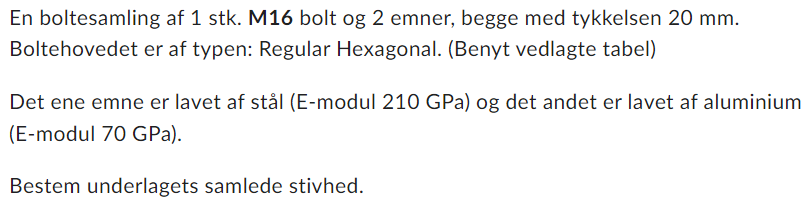

clear
format shortG
u = symunit;

W = 24 * u.mm;
d_w =  W;             % Nøglevidde/Washer face (tabel A-31 se under W)
H = 10.75 * u.mm;
d = 16 * u.mm;
t_a = 20 * u.mm;
t_s = 20 * u.mm;
A_d = pi/4 * d^2;   % Skaftareal [mm^2]

E_a = 70 * u.GPa;
E_s = 210 * u.GPa;

l = t_a + t_s    %Klemme længde (regnes kun til midt i underlagets nedre del) [mm]

$$l = 40\,\mathrm{mm}$$

L = t_a + t_s + H          % Boltlængde  [mm]

$$L = \frac{203}{4}\,\mathrm{mm}$$

A_t = 157 * u.mm;


%længde af gevind(L_T) følger normalt (8-14)

if separateUnits(L) <= 125 && separateUnits(d) <= 48
    L_T = 2*d + 6 * u.mm
elseif 125 < separateUnits(L) && separateUnits(L) <= 200
    L_T = 2 * d + 12 * u.mm
elseif separateUnits(L) > 200
    L_T = 2 * d + 25 * u.mm
else
    disp("Hmmm something is wrong")
end

$$L\_T = 38\,\mathrm{mm}$$



% Stivhed for matrialet med forskellige E-moduler
%ligges sammen til sidst.

%for alu
k_ma =  0.5774 * pi * E_a * d /...
    log( ((1.155 * t_a + d_w - d) * (d_w + d)) /...
    ((1.155 * t_a + d_w + d) * (d_w - d)) )

$$k\_ma = \frac{80836\,\pi }{125\,\log\left(\frac{1555}{631}\right)}\,\mathrm{GPa}\,\mathrm{mm}$$


k_ma = vpa(unitConvert(k_ma, u.MN), 5)

$$k\_ma = 2252.5\,\frac{\mathrm{MN}}{m}$$


% d_w_con = d_w + 2 * tand(alpha) * t_1 %forsatte spændings kegle efter alu

k_ms =  0.5774 * pi * E_s * d /...
    log( ((1.155 * t_s + d_w - d) * (d_w + d)) /...
    ((1.155 * t_s + d_w + d) * (d_w - d)) ) % her deles t_2 med 2 da det går over midten af spændings keglen

$$k\_ms = \frac{242508\,\pi }{125\,\log\left(\frac{1555}{631}\right)}\,\mathrm{GPa}\,\mathrm{mm}$$


k_ms = vpa(unitConvert(k_ms, u.MN), 5)

$$k\_ms = 6757.6\,\frac{\mathrm{MN}}{m}$$



% samlet stivhed her med et bidrag fra hvert matriale før peaket af keglen
% og et bidrag fra hvert matriale efter.
k_mtot = vpa(1/(1/k_ma + 1/k_ms), 5)

$$k\_mtot = 1689.4\,\frac{\mathrm{MN}}{m}$$

# Opgave 6

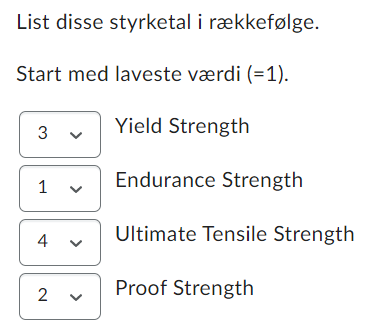

clear
format shortG
u = symunit;



# Opgave 7

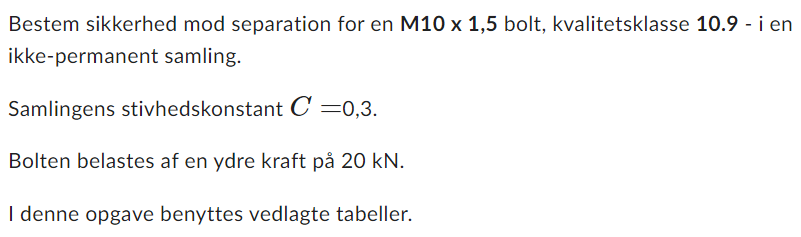

clear
format shortG
u = symunit;


d = 10 * u.mm;
p = 1.5 * u.mm;

C = 0.3;

P = 20 * u.kN;

A_t = 58 * u.mm^2;

S_p = 830 * u.MPa;



% Spændinger i bolten kan beregnes som
% sigma_b = F_b/A_t


P_m = P*(1 - C)

$$P\_m = 14\,\mathrm{kN}$$



% ANBEFALET FORSPÆNDING
F_p = A_t * S_p

$$F\_p = 48140\,\mathrm{MPa}\,{\mathrm{mm}}^{2}$$


F_i = unitConvert(0.75 * F_p, u.kN) % for IKKE permenente bolte ligning (8-31)

$$F\_i = \frac{7221}{200}\,\mathrm{kN}$$


n_0 = vpa(F_i / P_m, 3) %sikkerhed

$$n\_0 = 2.58$$

# Opgave 8

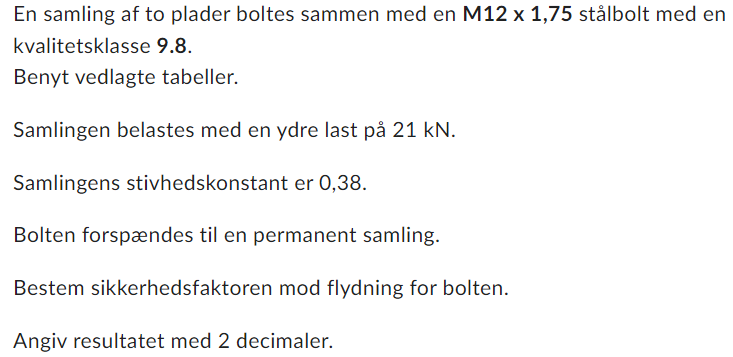

clear
format shortG
u = symunit;

d = 12 * u.mm;
p = 1.75 * u.mm;

S_p = 650 * u.MPa;

A_t = 84.3 * u.mm^2;


% S_y = 720 * u.MPa;

P = 21 * u.kN;

% ANBEFALET FORSPÆNDING
F_p = A_t * S_p

$$F\_p = 54795\,\mathrm{MPa}\,{\mathrm{mm}}^{2}$$


F_i = unitConvert(0.90 * F_p, u.kN) % for permenente bolte ligning (8-31)

$$F\_i = \frac{98631}{2000}\,\mathrm{kN}$$





%Samling stivhedskontanten
C =  0.38 

C =          0.38




% Spændinger i bolten kan beregnes som
% sigma_b = F_b/A_t

P_b = C * P

$$P\_b = \frac{399}{50}\,\mathrm{kN}$$

sigma_b = (F_i + P_b) / A_t

$$sigma\_b = \frac{38197}{56200}\,\frac{\mathrm{kN}}{{\mathrm{mm}}^{2}}$$


% Sikkerhed imod flydning

n_p = vpa(unitConvert(S_p / sigma_b, 'SI'), 2) % ligning 8-28

$$n\_p = 0.96$$

n_p = vpa(unitConvert(S_p * A_t / (C*P + F_i), 'SI'), 2)  % ligning 8-28

$$n\_p = 0.96$$

# Opgave 9

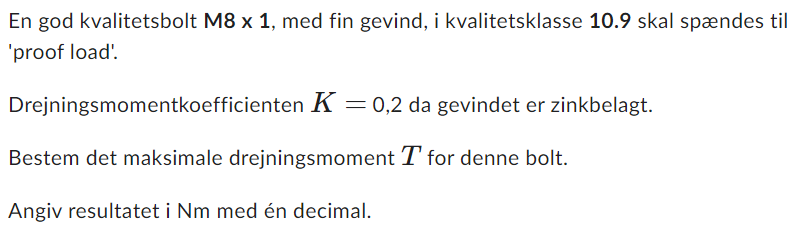

clear
format shortG
u = symunit;

d = 8 * u.mm;
p = 1 * u.mm;
S_p = 830 * u.MPa;

K = 0.2




# Opgave 10

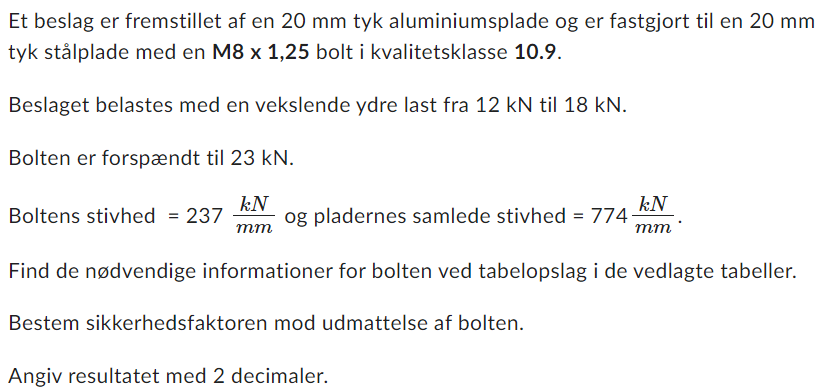

clear
format shortG
u = symunit;

A_t = 36.6 * u.mm^2;
F_i = 23 * u.kN;% Forspændingskraft på bolt 
k_b = 237 * u.kN / u.mm;% Boltens stivhed 
k_m = 774 * u.kN / u.mm;% Underlagets stivhed
P_min = 12 * u.kN;%Minimum ekstern belastning
P_max = 18 * u.kN;%Minimum ekstern belastning
S_ut = 1040 * u.MPa;
S_y = 940 * u.MPa;
S_e = 162 * u.MPa;

C = k_b / (k_b + k_b) % Samlingens stivhedskonstant

$$C = \frac{1}{2}$$

F_bmin = C * P_min + F_i

$$F\_bmin = 29\,\mathrm{kN}$$

F_bmax = C * P_max + F_i

$$F\_bmax = 32\,\mathrm{kN}$$



% udmattelses spændninger
% Amplitudespænding
% sigma_a = (sigma_max - sigma_min) / 2     %ligning 8-35
sigma_a = ((F_bmax - F_bmin) / 2) / A_t

$$sigma\_a = \frac{5}{122}\,\frac{\mathrm{kN}}{{\mathrm{mm}}^{2}}$$

sigma_a_ = vpa(unitConvert(sigma_a, u.MPa), 5)

$$sigma\_a\_ = 40.984\,\mathrm{MPa}$$

% sigma_a = C*(P_bmax - P_bmin) / (2*A_t)

sigma_m = ((F_bmax + F_bmin) / 2) / A_t

$$sigma\_m = \frac{5}{6}\,\frac{\mathrm{kN}}{{\mathrm{mm}}^{2}}$$


sigma_i = F_i / A_t

$$sigma\_i = \frac{115}{183}\,\frac{\mathrm{kN}}{{\mathrm{mm}}^{2}}$$


eta_e = S_e* ( S_ut - sigma_i) / (S_ut * sigma_a + S_e * (sigma_m - sigma_i)) 

$$eta\_e = \frac{9882\,\left(1040\,\mathrm{MPa}-\frac{115}{183}\,\frac{\mathrm{kN}}{{\mathrm{mm}}^{2}}\right)}{4625}\,\frac{{\mathrm{mm}}^{2}}{\mathrm{kN}}$$

eta_e_ = vpa(unitConvert(eta_e, 'SI'), 5)

$$eta\_e\_ = 0.87941$$

# Opgave 11

clear
format shortG
u = symunit;
